# Recepcion trama robot

## Objeto serial

baudRate=115200;
%serialportlist
%UsarACM0 para recibir datos de la Launchpad
%ACM1 no envía datos. Se usa para debug propio.
s=serialport("/dev/ttyACM0",baudRate,'Timeout',30)

s =   Serialport with properties:

                 Port: "/dev/ttyACM0"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


## Algunas configuraciones

dataMatrix=[];
configureTerminator(s,"CR/LF")
%s.Terminator
flush(s)

## Lectura

%while 1
dataRecieved=read(s,254,'uint8');
dataMatrix=[dataMatrix;dataRecieved];
%end

## Decodificación

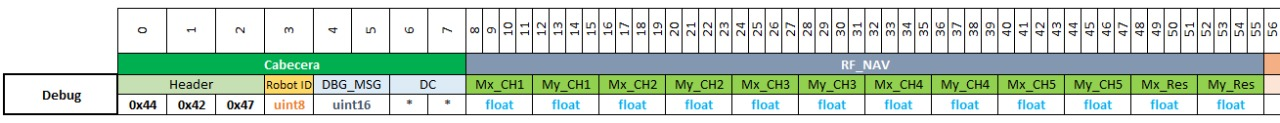

## Sólo para cargar archivos dummy

%load RFData.mat

## Preprocesamient

D=size(dataMatrix);
ind=D(1);

%Tabla de cabecera
Cabecera=array2table(zeros(D(1),3));
Cabecera_names=["Header" "Robot_ID" "DBG_MSG"];
Cabecera.Properties.VariableNames=Cabecera_names;
Cabecera.Header=string(Cabecera.Header);

%Tabla de navegación por RF
RF_NAV=array2table(zeros(D(1),12));
RF_NAV_names=["Mx_CH1" "My_CH1" "Mx_CH2" "My_CH2" "Mx_CH3" "My_CH3" "Mx_CH4" "My_CH4" "Mx_CH5" "My_CH5" "Mx_Res" "My_Res"];
RF_NAV.Properties.VariableNames=RF_NAV_names;

%Tabla de motores
MOTORS=array2table(zeros(D(1),4));
MOTORS_names=["Imot" "Isys" "MotorStatus" "IsysStatus"];
MOTORS.Properties.VariableNames=MOTORS_names;

%Tabla de bobina
BOBINA=array2table(zeros(D(1),15));
BOBINA_names=["ClusterSize" "BandsDetected" "PSD_B1" "PSD_B2" "PSD_B3" "PSD_B4" "PSD_B5" ...
    "PSD_B6" "PSD_B7" "PSD_B8" "PSD_B9" "PSD_B10" "PSD_B11" "PSD_Base" "BandsEmitted"];
BOBINA.Properties.VariableNames=BOBINA_names;

%Tabla navigation
NAVIGATION=array2table(zeros(D(1),9));
NAVIGATION_names=["CurrentState" "NextState" "nav_Cycs" "ACS" "LCS" "ClusterChanged" ...
     "BetterClusterFound" "MovStatus" "EscStrategy"];
NAVIGATION.Properties.VariableNames=NAVIGATION_names;

%Tabla RSSI
RSSI=array2table(zeros(12*D(1),7));
RSSI_names=["CH1" "CH2" "CH3" "CH4" "CH5" "Reading" "Angle"];
RSSI.Properties.VariableNames=RSSI_names;

%Tabla de datos
%READING_DATA=table(Cabecera,RF_NAV,MOTORS,BOBINA,NAVIGATION,RSSI);
%Por cada lectura

for i=1:D(1)
    
    %Cabecera
    Cabecera{i,"Header"}=string(char(uint8(dataMatrix(1,1:3))));       
    Cabecera{i,"Robot_ID"}=uint8(dataMatrix(i,4));    
    Cabecera{i,"DBG_MSG"}=typecast(uint8(dataMatrix(i,5:6)),'uint16');
                
    %RF_NAV
    for j=1:12    
        RF_NAV{i,j}=typecast(uint8(dataMatrix(i,(9:12)+4.*(j-1))),'single');
    end
    
    %Motores
    for j=1:4 
        if j<=2
        MOTORS{i,j}=typecast(uint8(dataMatrix(i,(57:60)+4.*(j-1))),'single');     
        else
        MOTORS{i,j}=typecast(uint8(dataMatrix(i,(65:66)+2.*(j-3))),'uint16');    
        end
    end
    
    %Tabla de bobina    
    BOBINA{i,"ClusterSize"}=typecast(uint8(dataMatrix(i,69:70)),'uint16');
    BOBINA{i,"BandsDetected"}=typecast(uint8(dataMatrix(i,71:72)),'uint16');
    for j=3:14
        BOBINA{i,j}=typecast(uint8(dataMatrix(i,(73:76)+4.*(j-3))),'single');     
    end
    BOBINA{i,"BandsEmitted"}=typecast(uint8(dataMatrix(i,121:122)),'uint16');
    
    %Navigaion
    NAVIGATION{i,"CurrentState"}=typecast(uint8(dataMatrix(i,125:128)),'int32');
    NAVIGATION{i,"NextState"}=typecast(uint8(dataMatrix(i,129:132)),'int32');
    NAVIGATION{i,"nav_Cycs"}=typecast(uint8(dataMatrix(i,133:134)),'uint16');
    NAVIGATION{i,"ACS"}=uint8(dataMatrix(i,135));
    NAVIGATION{i,"LCS"}=uint8(dataMatrix(i,136));
    NAVIGATION{i,"ClusterChanged"}=logical(dataMatrix(i,137));
    NAVIGATION{i,"BetterClusterFound"}=logical(dataMatrix(i,138));
    NAVIGATION{i,"MovStatus"}=uint8(dataMatrix(i,139));
    NAVIGATION{i,"ACS"}=uint8(dataMatrix(i,140));
    
    %Tabla RSSI
    RSSI{(1:12)+(i-1)*12,1:end-2}=reshape(uint8(dataMatrix(i,141:200)),5,12)';
    RSSI{(1:12)+(i-1)*12,"Reading"}=repmat(i,12,1);
    RSSI{(1:12)+(i-1)*12,"Angle"}=(1:12)';
    
    %Estadistica de RSSI
    %for k=1:20
    RSSI_statistics_data=RSSI{(1:12)+12*(i-1),["CH1" "CH2" "CH3" "CH4" "CH5"]};
    RSSI_statistics_median(i,:)=median(RSSI_statistics_data);    
    RSSI_statistics_3Q(i,:)=quantile(RSSI_statistics_data,0.75);
    RSSI_statistics_1Q(i,:)=quantile(RSSI_statistics_data,0.25);
    %end
end



## RSSI Subplot

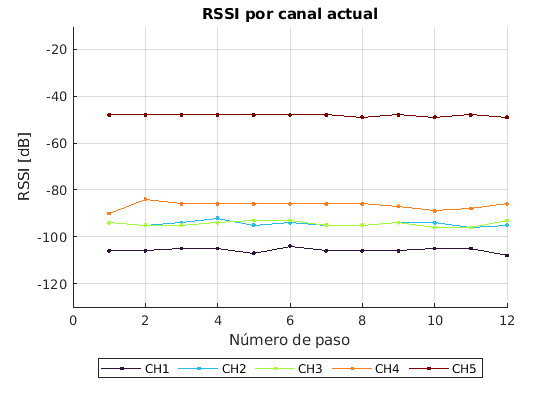

%% Ploteo
cmap=turbo(5);
id_state=NAVIGATION.CurrentState==1;

%Lectura actual
figure
%subplot(2,1,1)
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(RSSI.Angle(end-11:end),-RSSI{end-11:end,1:5},'.-')
%colormap turbo
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Número de paso")
ylim([-130 -10])
title("RSSI por canal actual")
grid on

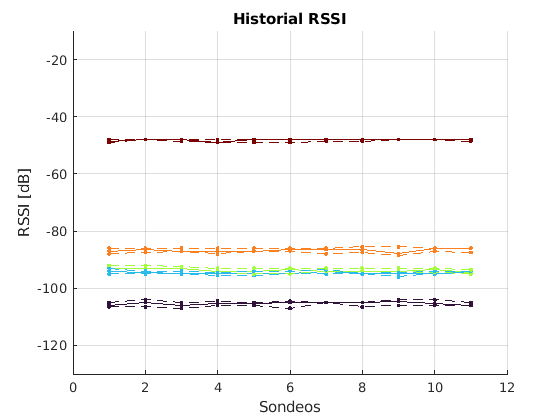


%Lecturas pasadas
%subplot(2,1,2)
figure
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(-RSSI_statistics_median(id_state,:),'.-')
%colormap turbo
hold on
plot(-RSSI_statistics_3Q(id_state,:),'.--')
%colormap turbo
plot(-RSSI_statistics_1Q(id_state,:),'.--')
%colormap turbo
hold off
ylabel("RSSI [dB]")
xlabel("Sondeos")
title("Historial RSSI")
ylim([-130 -10])
grid on

%end

## RSSI Lineal

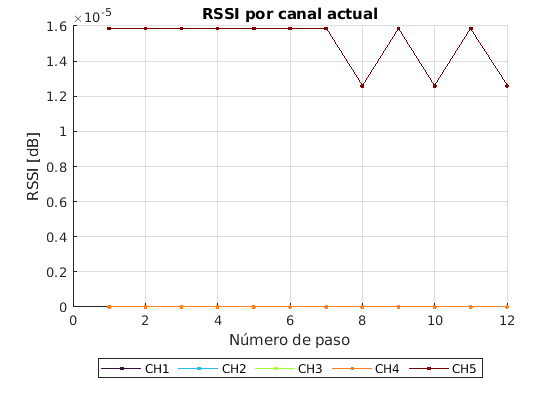

%Lectura actual
figure
%subplot(2,1,1)   
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(RSSI.Angle(end-11:end),10.^((-RSSI{end-11:end,1:5})./10),'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Número de paso")
%ylim([-130 -10])
title("RSSI por canal actual")
grid on

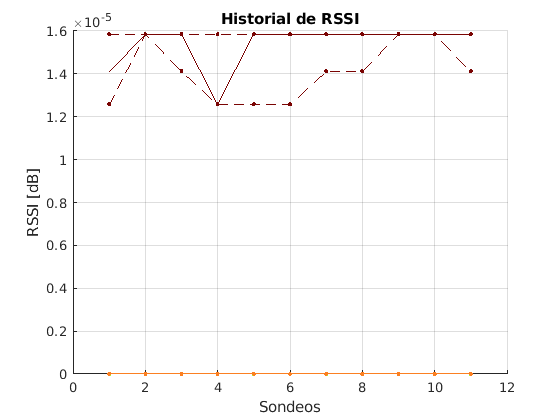


%Lecturas pasadas
figure
%subplot(2,1,2)
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(10.^(-RSSI_statistics_median(id_state,:)./10))
hold on
plot(10.^(-RSSI_statistics_3Q(id_state,:)./10),'.--')
plot(10.^(-RSSI_statistics_1Q(id_state,:)./10),'.--')
hold off
ylabel("RSSI [dB]")
xlabel("Sondeos")
title("Historial de RSSI")
grid on

%ylim([-130 -10])
%end


## Graficado

% %tiledlayout('flow')
% figure
% %nexttile
% plot(MOTORS{:,["Imot" "Isys"]},'o-')
% ylabel("[mA]")
% title("Consumo de corriente")
% legend(["Motores" "Sistema"])
% 


## Potencia en bobinas


% figure
% %plot(BOBINA{:,3:14},'o-')
% bar(BOBINA{:,3:15})
% ylabel("PSD Total [V^2/Hz]")
% title("Potencia espectral en bobinas")
% legend(["B"+(1:11) "Umbral"],'Location',"eastoutside")


## Cluster size

% figure
% bar(BOBINA{:,["ClusterSize" "BandsDetected" "BandsEmitted"]})
% legend(["ClusterSize" "BandsDetected" "BandsEmitted"])
% %Bands emited y detectadas
% %dec2bin(typecast(uint8(dataMatrix(i,71:72)),'uint16'),16)
% %el resultado se lee de derecha a izquierda
% %Cada bit representa una banda

## RSSI

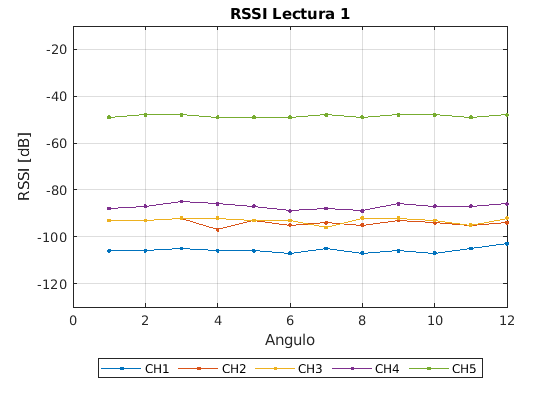


%readingNo=max(RSSI.Reading);


readingNo=1;
index=RSSI.Reading==readingNo;


figure
%gscatter(RSSI.Angle,RSSI{:,1:5},RSSI.Angle)
title("RSSI por canal")
plot(RSSI.Angle(index),-RSSI{index,1:5},'.-')
%plot(RSSI.Angle(end-11:end),-RSSI{end-11:end,1:5},'-o')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Angulo")
ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on

## Lectura actual

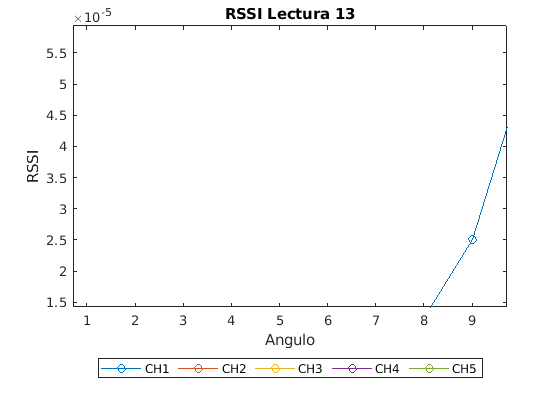

readingNo=13;
index=RSSI.Reading==readingNo;
figure
    plot(RSSI.Angle(index),10.^((-RSSI{index,1:5})./10),'-o')
    legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
    ylabel("RSSI")
    xlabel("Angulo")
    %ylim([-130 -10])
    title("RSSI Lectura "+readingNo)

## RSSI por lectura

% readingNo=max(RSSI.Reading);
% %index=RSSI.Reading==readingNo;
% figure
% %gscatter(RSSI.Angle,RSSI{:,1:5},RSSI.Angle)
% title("RSSI contra lectura")
% plot(RSSI.Reading,-RSSI{:,1:5},'-o')
% legend(["CH1" "CH2" "CH3" "CH4" "CH5"])
% ylabel("RSSI [dB]")
% xlabel("Angulo")
% ylim([-130 -10])
% title("RSSI Lectura "+readingNo)